# **LISTA 2 - ELEMENTOS FINITOS PARA ESTRUTURAS UNIDIMENSIONAIS DE BARRA**

### **Aluno: Leonardo Silveira Leite - RA: 291646**

*Obs.: O presente Live Script foi desenvolvido para determinados tópicos do exercício II da Lição 2 - Elementos Finitos para Estruturas Unidimensionais de Barra.*

#### EXERCÍCIO II - Seção Variável

(6) Desenvolver um código em Matlab que permita resolver o problema com um número arbitrário de elementos. O programa deve calcular: deslocamentos, deformações, tensões e as normas L2 do erro com respeito a solução analítica.

(7) Usar malhas de 4, 8, 16 e 32 elementos e calcular os erros de aproximação na norma L2. Comentar os resultados.

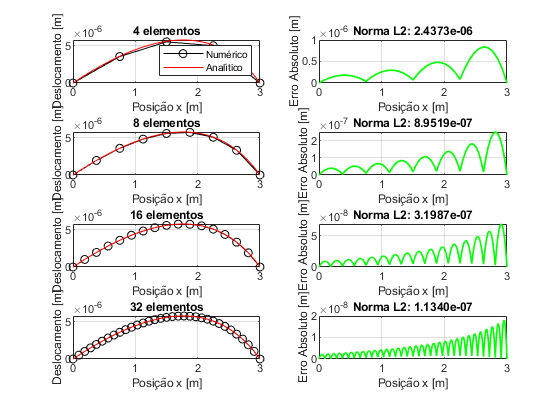

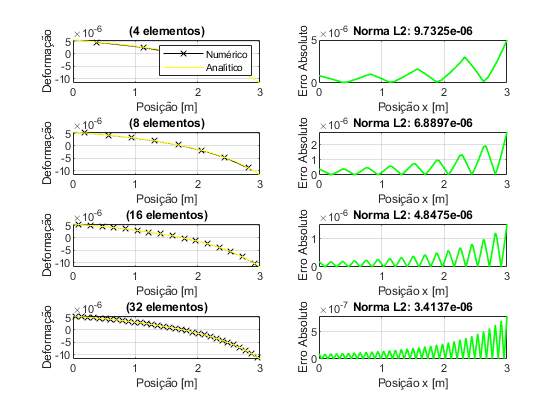

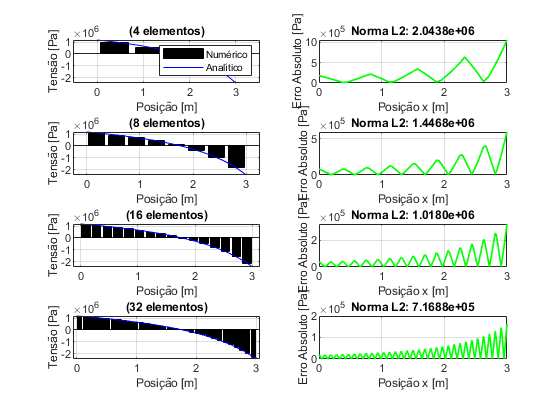

clc; clear all;

%% Parâmetros de entrada
E = 210e9;      % Módulo de elasticidade (Pa)
A0 = 0.001;     % Área na seção transversal no ponto x = 0 (m²)
AI = 3*A0;      % Área na seção transversal no ponto x = L (m²)
P0 = 2000;      % Carga distribuída
L = 3;          % Comprimento total da barra (m)
F = 0;          % Carga pontual na extremidade direita (N)

nels = [4, 8, 16, 32];

%% Resolução
for n_idx = 1:length(nels)
    nel = nels(n_idx);
    nnos = nel + 1;
    h = L / nel;
    coord = [0:h:L];
    inci = [[1:nnos-1]' [2:nnos]'];

    Kg = zeros(nnos, nnos);
    Fg = zeros(nnos, 1);

    % Montagem da matriz de rigidez global
    for e = 1:nel
        % Coordenadas do elemento
        x1 = coord(inci(e, 1));
        x2 = coord(inci(e, 2));

        % Áreas nos pontos x1 e x2 (variação linear)
        A1 = A0 * (3 - (2 * x1 / L));
        A2 = A0 * (3 - (2 * x2 / L));

        % Rigidez do elemento
        ke = (E / (x2 - x1)) * [(A1 + A2) / 2, -(A1 + A2) / 2; -(A1 + A2) / 2, (A1 + A2) / 2];
        fe = (P0 * h / 2) * [1; 1];

        % Montagem na matriz global
        Kg(inci(e,:), inci(e,:)) = Kg(inci(e,:), inci(e,:)) + ke;
        Fg(inci(e,:)) = Fg(inci(e,:)) + fe;
    end

    % Condições de contorno
    Fg(nnos) = Fg(nnos) + F;
    freedofs = 2:(nnos-1);

    % Inicializar vetor de deslocamento
    u = zeros(nnos, 1);
    u(freedofs) = Kg(freedofs, freedofs) \ Fg(freedofs);

    % Calcular forças nodais reativas
    FR = Kg * u;
    T = zeros(nel, 1);
    def = zeros(nel, 1);

    % Pré-alocar o vetor coord_mid para os pontos médios de cada elemento
    coord_mid = zeros(1, nel);

    % Calcular as coordenadas dos pontos médios
    for i = 1:nel
        coord_mid(i) = (coord(i) + ((coord(i+1) - coord(i)) / 2));
    end

    % Calculo das tensões dentro de cada elemento
    somaF = 0;
    for j = 1:(nnos-1)
        % Calculando a área média usando a função de área variável
        A1 = A0 * (3 - (2 * coord(j) / L));
        A2 = A0 * (3 - (2 * coord(j+1) / L));
        Am = (A1 + A2) / 2;

        % Cálculo da tensão
        somaF = somaF + FR(j);
        FIE = -somaF;
        Te = (FIE / Am);
        T(j,1) = Te;
        
        % Cálculo da deformação
        dfm = Te / E;
        def(j,1) = dfm;
    end

    % Solução analítica 
    x = [0:h/10:L];
    ua = (-P0 * L^2 / (4 * A0 * E)) * ((3 - (2 * x) / L) - 3 * log(3 - (2 * x) / L)) ...
        - ((3 * P0 * L / 2 - (P0 * L) / log(3)) * L / (2 * E * A0)) * log(3 - (2 * x) / L) ...
        + (P0 * L^2) / (4 * E * A0);

    % Cálculo da deformação
    dudx = (-P0 * L^2 / (4 * A0 * E)) * (-2 / L + 6 ./ (L * (3 - (2 * x) / L))) ...
        - ((3 * P0 * L / 2 - P0 * L / log(3)) * L / (2 * E * A0)) * (-2 ./ (L * (3 - (2 * x) / L)));
    
    % Cálculo da tensão
    sxx = dudx * E;

    %% ERROS 
    % ERROS DO DESLOCAMENTO INTERPOLANDO PELAS FUNÇÕES DE FORMA DO ELEMENTO
    u_interp = zeros((nnos * 10) - 10, 1);
    d_interp = zeros((nnos * 10) - 10, 1);
    t_interp = zeros((nnos * 10) - 10, 1);

    % Loop sobre cada elemento
    for i = 1:nel
        no1 = inci(i,1);
        no2 = inci(i,2);
        u1 = u(no1);
        u2 = u(no2);
        xx = linspace(h/10, h - (h/10), 9);

        for j = 1:9
            d_interpele = def(i);
            d_interp(((no1 - 1) * 10) + (1 + j)) = d_interpele;
            d_interp((no2 * 10) - 9) = d_interpele;
            d_interp(1) = def(1);
            
            t_interpele = T(i);
            t_interp(((no1 - 1) * 10) + (1 + j)) = t_interpele;
            t_interp((no2 * 10) - 9) = t_interpele;
            t_interp(1) = T(1);

            N1 = ((h) - xx(j)) / h;
            N2 = xx(j) / h;
            u_interpele = N1 * u1 + N2 * u2;
            u_interp(((no1 - 1) * 10) + (1 + j)) = u_interpele;
        end
        u_interp(((no1 - 1) * 10) + 11) = u(no2);
    end

    erro_absolut = abs(ua - u_interp');
    erro_absolut2 = abs(sxx - t_interp');
    erro_absolut3 = abs(dudx - d_interp');
    erro_euclidiano1 = norm(erro_absolut);
    erro_euclidiano2 = norm(erro_absolut2);
    erro_euclidiano3 = norm(erro_absolut3);

    %% Plotagem
    % Deslocamento
    figure(1);
    subplot(length(nels), 2, 2*n_idx-1);
    plot(coord, u, 'o-k', x, ua, '-r');
    grid on; xlabel('Posição x [m]'); ylabel('Deslocamento [m]');
    title(sprintf('%d elementos', nel));
    if n_idx == 1
        legend('Numérico', 'Analítico');
    end

    subplot(length(nels), 2, 2*n_idx);
    plot(x, erro_absolut, '-g', 'LineWidth', 1.25); 
    title(sprintf('Norma L2: %.4e', erro_euclidiano1)); grid on;
    xlabel('Posição x [m]'); ylabel('Erro Absoluto [m]'); hold on;

    % Deformação
    figure(2);
    subplot(length(nels), 2, 2*n_idx-1);
    plot(coord_mid, def, 'x-k', x, dudx, 'y'); hold on; grid on;
    xlabel('Posição [m]'); ylabel('Deformação');
    title(sprintf('(%d elementos)', nel));
    if n_idx == 1
        legend('Numérico', 'Analítico');
    end

    subplot(length(nels), 2, 2*n_idx);
    plot(x, erro_absolut3, '-g', 'LineWidth', 1.25); 
    title(sprintf('Norma L2: %.4e', erro_euclidiano3)); grid on;
    xlabel('Posição x [m]'); ylabel('Erro Absoluto');
    hold off;
    
    % Tensão
    figure(3);
    subplot(length(nels), 2, 2*n_idx-1);
    bar((coord(1:end-1) + coord(2:end)) / 2, T, 'FaceColor', 'k'); hold on;
    plot(x, sxx, '-b'); grid on;
    xlabel('Posição [m]'); ylabel('Tensão [Pa]');
    title(sprintf('(%d elementos)', nel));
    if n_idx == 1
        legend('Numérico', 'Analítico');
    end

    subplot(length(nels), 2, 2*n_idx);
    plot(x, erro_absolut2, '-g', 'LineWidth', 1.25); 
    title(sprintf('Norma L2: %.4e', erro_euclidiano2)); grid on;
    xlabel('Posição x [m]'); ylabel('Erro Absoluto [Pa]');
    hold off;
end

(8) Determinar o sistema de equações para o elemento finito de 3 nós com aproximação quadrática usando o espaço isoparamétrico definido entre [-1, 1]. Calcular as matrizes de rigidez e vetor de carga nodal equivalente. Implementar e comparar com os resultados obtidos com o elemento de 2 nós. Comentar os resultados.

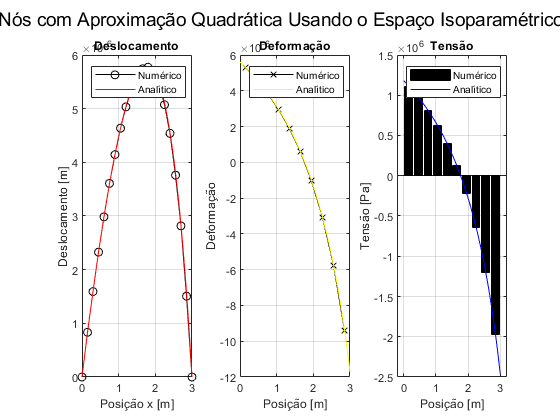

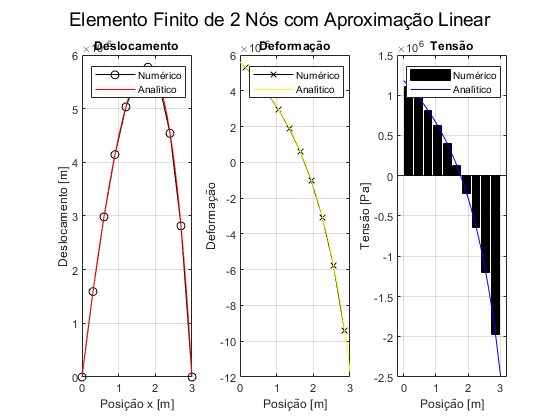

clc; clear all;

%% Parâmetros de entrada
E = 210e9;      % Módulo de elasticidade (Pa)
A0 = 0.001;     % Área na seção transversal no ponto x = 0 (m²)
AI = 3 * A0;    % Área na seção transversal no ponto x = L (m²)
P0 = 2000;      % Carga distribuída (N/m)
L = 3;          % Comprimento total da barra (m)
F = 0;          % Carga pontual na extremidade direita (N)

nels = [10]; % Diferentes refinamentos de malha

%% Resolução
for n_idx = 1:length(nels)
    nel = nels(n_idx);                          % Número de elementos
    nnos = 2 * nel + 1;                         % Número de nós (2 nós por elemento + 1 nó intermediário)
    h = L / nel;                                % Tamanho de cada elemento
    coord = linspace(0, L, nnos);               % Coordenadas dos nós
    inci = [1:2:nnos-2; 2:2:nnos-1; 3:2:nnos]'; % Incidência dos elementos (3 nós por elemento)

    % Inicializar matriz de rigidez global e vetor de forças
    Kg = zeros(nnos, nnos);
    Fg = zeros(nnos, 1);

    % Loop sobre os elementos para montar a matriz global
    for e = 1:nel
        % Nós do elemento
        n1 = inci(e, 1);
        n2 = inci(e, 2);
        n3 = inci(e, 3);
        xe = coord([n1, n2, n3]); % Coordenadas dos nós do elemento

        % Área nos nós e média do elemento
        A1 = A0 * (3 - (2 * xe(1)) / L);
        A2 = A0 * (3 - (2 * xe(2)) / L);
        A3 = A0 * (3 - (2 * xe(3)) / L);
        Am = (A1 + A2 + A3) / 3;

        % Matriz de rigidez local (2 pontos de Gauss)
        xi_gauss = [-sqrt(1/3), sqrt(1/3)]; % Pontos de integração
        w_gauss = [1, 1];                   % Pesos de integração
        Ke = zeros(3, 3);                   % Matriz de rigidez local
        fe = zeros(3, 1);                   % Força local

        for i = 1:length(xi_gauss)
            xi = xi_gauss(i); % Ponto de Gauss
            w = w_gauss(i);  % Peso de Gauss

            % Funções de forma e derivadas
            N = [(xi-1)*xi/2, (1-xi^2), (xi+1)*xi/2]; % Funções de forma
            dNdxi = [(2*xi-1)/2, -2*xi, (2*xi+1)/2];  % Derivadas das funções de forma

            % Determinante do Jacobiano
            J = (xe(3) - xe(1)) / 2;
            dNdx = dNdxi / J;

            % Rigidez local
            Ke = Ke + (E * Am) * (dNdx' * dNdx) * J * w;

            % Força local
            fe = fe + P0 * N' * J * w;
        end

        % Montagem na matriz global
        Kg([n1, n2, n3], [n1, n2, n3]) = Kg([n1, n2, n3], [n1, n2, n3]) + Ke;
        Fg([n1, n2, n3]) = Fg([n1, n2, n3]) + fe;
    end

    % Condições de contorno
    Fg(nnos) = Fg(nnos) + F;
    free_dofs = 2:(nnos-1);

    % Resolver o sistema para os deslocamentos
    u = zeros(nnos, 1);
    u(free_dofs) = Kg(free_dofs, free_dofs) \ Fg(free_dofs);

    % Forças de reação
    FR = Kg * u;

    % Calcular tensões e deformações
    T = zeros(nel, 1);
    def = zeros(nel, 1);
    for e = 1:nel
        n1 = inci(e, 1);
        n2 = inci(e, 2);
        n3 = inci(e, 3);
        ue = u([n1, n2, n3]);

        % Cálculo da tensão (em 2 pontos de Gauss)
        T_gauss = zeros(2, 1);
        for i = 1:2
            xi = xi_gauss(i);
            dNdxi = [(2*xi-1)/2, -2*xi, (2*xi+1)/2];
            J = (coord(n3) - coord(n1)) / 2;
            dNdx = dNdxi / J;
            T_gauss(i) = E * (dNdx * ue);
        end
        T(e) = mean(T_gauss);
        def(e) = T(e) / E;
    end

    % Solução analítica
    x = linspace(0, L, 100);
    ua = (-P0 * L^2 / (4 * A0 * E)) * ((3 - (2 * x) / L) - 3 * log(3 - (2 * x) / L)) ...
        - ((3 * P0 * L / 2 - (P0 * L) / log(3)) * L / (2 * E * A0)) * log(3 - (2 * x) / L) ...
        + (P0 * L^2) / (4 * E * A0);
    
    % Cálculo da deformação
    dudx = (-P0 * L^2 / (4 * A0 * E)) * (-2 / L + 6 ./ (L * (3 - (2 * x) / L))) ...
        - ((3 * P0 * L / 2 - P0 * L / log(3)) * L / (2 * E * A0)) * (-2 ./ (L * (3 - (2 * x) / L)));
    
    % Cálculo da tensão
    sxx = dudx * E;
    
    % Coordenadas médias dos elementos
    coord_mid = zeros(nel, 1);
    for e = 1:nel
        n1 = inci(e, 1);
        n3 = inci(e, 3);
        coord_mid(e) = (coord(n1) + coord(n3)) / 2;
    end

    %% Plotagem combinada em um único figure
    figure;
    sgtitle('Elemento Finito de 3 Nós com Aproximação Quadrática Usando o Espaço Isoparamétrico Definido entre [-1, 1]', 'FontSize', 14);

    % Deslocamento
    subplot(1, 3, 1);
    plot(coord, u, 'o-k', x, ua, '-r');
    grid on;
    xlabel('Posição x [m]');
    ylabel('Deslocamento [m]');
    title(sprintf('Deslocamento'));
    if n_idx == 1
        legend('Numérico', 'Analítico');
    end

    % Deformação
    subplot(1, 3, 2);
    plot(coord_mid, def, 'x-k', x, dudx, 'y'); hold on;
    grid on;
    xlabel('Posição [m]');
    ylabel('Deformação');
    title(sprintf('Deformação'));
    if n_idx == 1
        legend('Numérico', 'Analítico');
    end

    % Tensão
    subplot(1, 3, 3);
    bar(coord_mid, T, 'FaceColor', 'k'); hold on;
    plot(x, sxx, '-b');
    grid on;
    xlabel('Posição [m]');
    ylabel('Tensão [Pa]');
    title(sprintf('Tensão'));
    if n_idx == 1
        legend('Numérico', 'Analítico');
    end
end

(10) Implemente o cálculo do vetor de carga nodal equivalente da estrutura completa, para uma malha com um número arbitrário de elementos. Resolva o sistema e analise as soluções obtidas para deslocamentos, deformações e tensões.

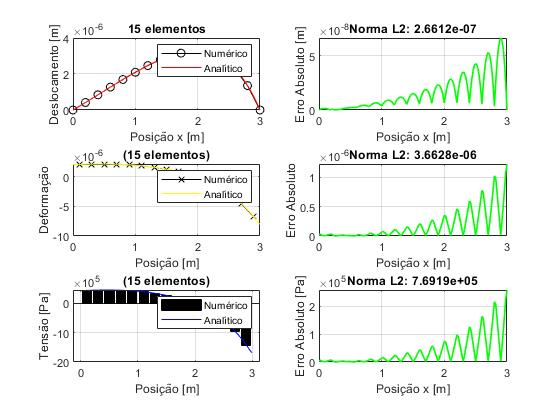

clc; clear all;

%% Parâmetros de entrada
E = 210e9;      % Módulo de elasticidade (Pa)
A0 = 0.001;     % Área na seção transversal no ponto x = 0 (m²)
AI = 3*A0;      % Área na seção transversal no ponto x = L (m²)
P0 = 2000;      % Carga distribuída
L = 3;          % Comprimento total da barra (m)
F = 0;          % Carga pontual na extremidade direita (N)

nels = 15;

%% Resolução
for n_idx = 1:length(nels)
    nel = nels(n_idx);
    nnos = nel + 1;
    h = L / nel;
    coord = [0:h:L];
    inci = [[1:nnos-1]' [2:nnos]'];

    Kg = zeros(nnos, nnos);
    Fg = zeros(nnos, 1);
    Bg = [-1/h 1/h];

    % Montagem da matriz de rigidez global
    for e = 1:nel
        % Coordenadas do elemento
        x1 = coord(inci(e, 1));
        x2 = coord(inci(e, 2));

        % Áreas nos pontos x1 e x2
        A1 = A0 * (3 - (2 * x1 / L));
        A2 = A0 * (3 - (2 * x2 / L));

        % Rigidez do elemento
        ke = (2 * E / (x2 - x1)) * [(A1 + A2) / 2, -(A1 + A2) / 2; -(A1 + A2) / 2, (A1 + A2) / 2];
        f1 = P0 * x1 / L;
        f2 = P0 * x2 / L; 
        fe = (h / 6) * [2*f1 + f2; f1 + 2*f2];

        % Montagem na matriz global
        Kg(inci(e,:), inci(e,:)) = Kg(inci(e,:), inci(e,:)) + ke;
        Fg(inci(e,:)) = Fg(inci(e,:)) + fe(1);
        Fg(inci(e,:)) = Fg(inci(e,:)) + fe(2);
    end

    % Condições de contorno
    Fg(nnos) = Fg(nnos) + F;
    freedofs = 2:(nnos-1);

    % Inicializar vetor de deslocamento
    u = zeros(nnos, 1);
    u(freedofs) = Kg(freedofs, freedofs) \ Fg(freedofs);

    % Calcular forças nodais reativas
    FR = Kg * u;
    T = zeros(nel, 1);
    def = zeros(nel, 1);

    % Pré-alocar o vetor coord_mid para os pontos médios de cada elemento
    coord_mid = zeros(1, nel);

    % Calcular as coordenadas dos pontos médios
    for i = 1:nel
        coord_mid(i) = (coord(i) + ((coord(i+1) - coord(i)) / 2));
    end

    % Calculo das tensões e deformações dentro de cada elemento
    for j = 1:nel
        % Coordenadas do elemento
        x1 = coord(inci(j,1));
        x2 = coord(inci(j,2));
        u1 = u(inci(j,1));
        u2 = u(inci(j,2));

        % Áreas nos extremos do elemento
        A1 = A0 * (3 - (2 * x1 / L));
        A2 = A0 * (3 - (2 * x2 / L));
        Am = (A1 + A2) / 2;

        % Deformação (gradiente de deslocamento)
        DEF(j) = (u2 - u1) / (x2 - x1);

        % Tensão (Lei de Hooke)
        T(j) = E * DEF(j);
    end


    %% Solução analítica 
    % Cálculo do deslocamento
    x = [0:h/10:L];
    ua = (P0 * L^2 / (16 * A0 * E)) * (((3 - (2 * x) / L).^2) / 2 - 6 .* (3 - (2 * x) / L) + 9 .* log(3 - (2 * x) / L)) ...
    - (((-P0 * L / log(3)) + (9 * P0 * L) / 8) * L) / (2 * E * A0) .* log(3 - (2 * x) / L) ...
    + (11 * P0 * L^2) / (32 * E * A0);

    % Cálculo da deformação
    dudx = gradient(ua,x);

    % Cálculo da tensão
    sxx = dudx * E;

    %% ERROS 
    % ERROS DO DESLOCAMENTO INTERPOLANDO PELAS FUNÇÕES DE FORMA DO ELEMENTO
    u_interp = zeros((nnos * 10) - 10, 1);
    d_interp = zeros((nnos * 10) - 10, 1);
    t_interp = zeros((nnos * 10) - 10, 1);

    % Loop sobre cada elemento
    for i = 1:nel
        no1 = inci(i,1);
        no2 = inci(i,2);
        u1 = u(no1);
        u2 = u(no2);
        xx = linspace(h/10, h - (h/10), 9);

        for j = 1:9
            d_interpele = DEF(i);
            d_interp(((no1 - 1) * 10) + (1 + j)) = d_interpele;
            d_interp((no2 * 10) - 9) = d_interpele;
            d_interp(1) = DEF(1);
            
            t_interpele = T(i);
            t_interp(((no1 - 1) * 10) + (1 + j)) = t_interpele;
            t_interp((no2 * 10) - 9) = t_interpele;
            t_interp(1) = T(1);

            N1 = ((h) - xx(j)) / h;
            N2 = xx(j) / h;
            u_interpele = N1 * u1 + N2 * u2;
            u_interp(((no1 - 1) * 10) + (1 + j)) = u_interpele;
        end
        
        u_interp(((no1 - 1) * 10) + 11) = u(no2);
    end

    erro_absolut = abs(ua - u_interp');
    erro_absolut2 = abs(sxx - t_interp');
    erro_absolut3 = abs(dudx - d_interp');
    erro_euclidiano1 = norm(erro_absolut);
    erro_euclidiano2 = norm(erro_absolut2);
    erro_euclidiano3 = norm(erro_absolut3);

    %% Plotagem
    % Deslocamento
    figure(1);
    subplot(3,2,1);
    plot(coord, u, 'o-k', x, ua, '-r');
    grid on; xlabel('Posição x [m]'); ylabel('Deslocamento [m]');
    title(sprintf('%d elementos', nel));
    if n_idx == 1
        legend('Numérico', 'Analítico');
    end

    subplot(3,2,2);
    plot(x, erro_absolut, '-g', 'LineWidth', 1.25); 
    title(sprintf('Norma L2: %.4e', erro_euclidiano1)); grid on;
    xlabel('Posição x [m]'); ylabel('Erro Absoluto [m]'); hold on;

    % Deformação
    subplot(3,2,3);
    plot(coord_mid, DEF, 'x-k', x, dudx, 'y'); hold on; grid on;
    xlabel('Posição [m]'); ylabel('Deformação');
    title(sprintf('(%d elementos)', nel));
    if n_idx == 1
        legend('Numérico', 'Analítico');
    end

    subplot(3,2,4);
    plot(x, erro_absolut3, '-g', 'LineWidth', 1.25); 
    title(sprintf('Norma L2: %.4e', erro_euclidiano3)); grid on;
    xlabel('Posição x [m]'); ylabel('Erro Absoluto');
    hold off;
    
    % Tensão
    subplot(3,2,5);
    bar((coord(1:end-1) + coord(2:end)) / 2, T, 'FaceColor', 'k'); hold on;
    plot(x, sxx, '-b'); grid on;
    xlabel('Posição [m]'); ylabel('Tensão [Pa]');
    title(sprintf('(%d elementos)', nel));
    if n_idx == 1
        legend('Numérico', 'Analítico');
    end

    subplot(3,2,6);
    plot(x, erro_absolut2, '-g', 'LineWidth', 1.25); 
    title(sprintf('Norma L2: %.4e', erro_euclidiano2)); grid on;
    xlabel('Posição x [m]'); ylabel('Erro Absoluto [Pa]');
    hold off;
end